% mikexcohen.com

## complex sine waves

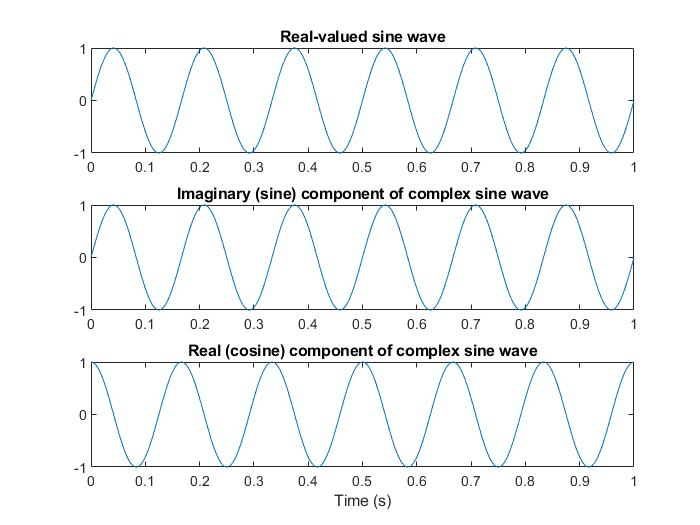

srate = 1000;
time  = 0:1/srate:1;
freq  = 6;


realval_sine = sin(2*pi*freq*time);
complex_sine = exp(1i*2*pi*freq*time);

figure(1), clf
% plot "normal" sine wave
subplot(311)
plot(time,realval_sine)
title('Real-valued sine wave')

% plot real part
subplot(312)
plot(time,imag(complex_sine))
title('Imaginary (sine) component of complex sine wave')

% plot imaginary part
subplot(313)
plot(time,real(complex_sine))
title('Real (cosine) component of complex sine wave')
xlabel('Time (s)')

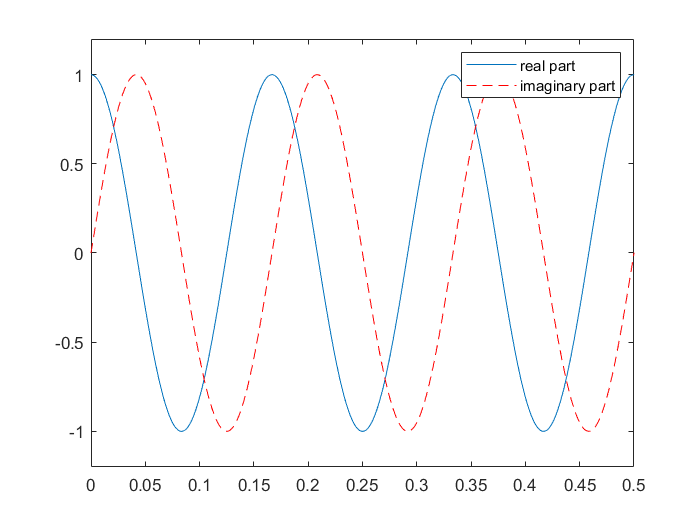


figure(2), clf
plot(time,real(complex_sine))
hold on
plot(time,imag(complex_sine),'r--')
set(gca,'ylim',[-1.2 1.2],'xlim',[0 .5])
legend({'real part';'imaginary part'})

## other ways to look at complex sine waves

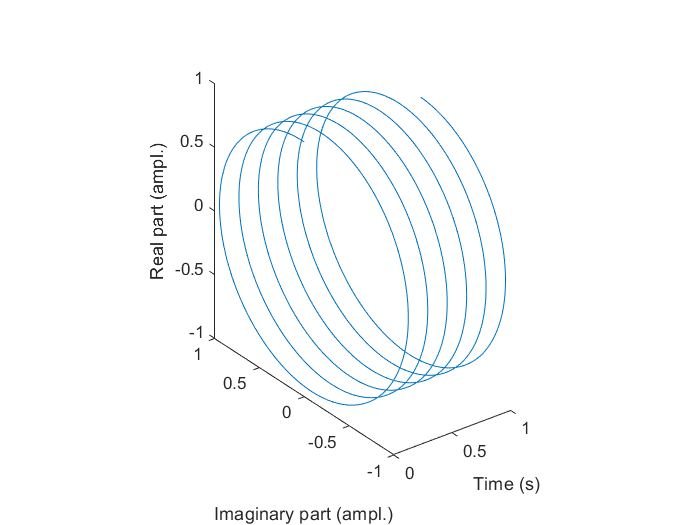

figure(3), clf

plot3(time,imag(complex_sine),real(complex_sine))
xlabel('Time (s)'), ylabel('Imaginary part (ampl.)'), zlabel('Real part (ampl.)')
axis image

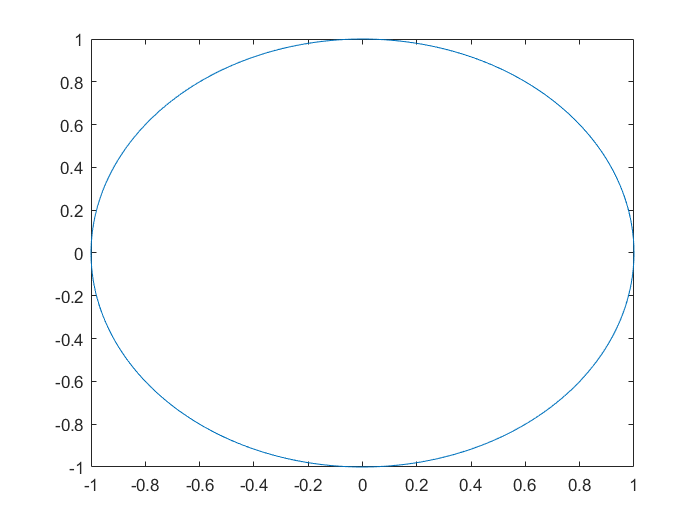

rotate3d


figure(4), clf
plot(imag(complex_sine),real(complex_sine))

% plot(complex_sine)

## Fourier coefficients as complex numbers

% create sine waves that differ in power and phase
sine1 = 3 * cos(2*pi*freq*time + 0 );
sine2 = 2 * cos(2*pi*freq*time + pi/6 );
sine3 = 1 * cos(2*pi*freq*time + pi/3 );

% compute Fourier coefficients
fCoefs1 = fft(sine1) / length(time);
fCoefs2 = fft(sine2) / length(time);
fCoefs3 = fft(sine3) / length(time);

hz = linspace(0,srate/2,floor(length(time)/2)+1);

% find the frequency of our sine wave
% extract just the Fourier coff. at 6Hz
hz6 = dsearchn(hz',freq);

% let's look at the coefficients for this frequency
disp([ '6 Hz Fourier coefficient for sin1: ' num2str(fCoefs1(hz6)) ])

6 Hz Fourier coefficient for sin1: 1.5004+0.028257i


disp([ '6 Hz Fourier coefficient for sin2: ' num2str(fCoefs2(hz6)) ])

6 Hz Fourier coefficient for sin2: 0.85684+0.51595i


disp([ '6 Hz Fourier coefficient for sin3: ' num2str(fCoefs3(hz6)) ])

6 Hz Fourier coefficient for sin3: 0.24192+0.4374i


## complex numbers as vectors in a polar plot

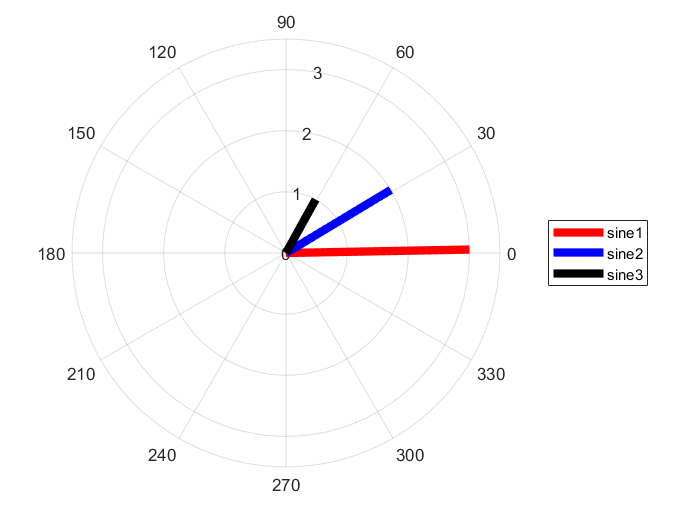

% make polar plots of fourier coefficients
figure(5), clf
h(1) = polarplot([0 angle(fCoefs1(hz6))],[0 2*abs(fCoefs1(hz6))],'r');
hold on
h(2) = polarplot([0 angle(fCoefs2(hz6))],[0 2*abs(fCoefs2(hz6))],'b');
h(3) = polarplot([0 angle(fCoefs3(hz6))],[0 2*abs(fCoefs3(hz6))],'k');
set(h,'linewidth',5)
legend({'sine1';'sine2';'sine3'})

## phase and power information can be extracted via Euler's formula

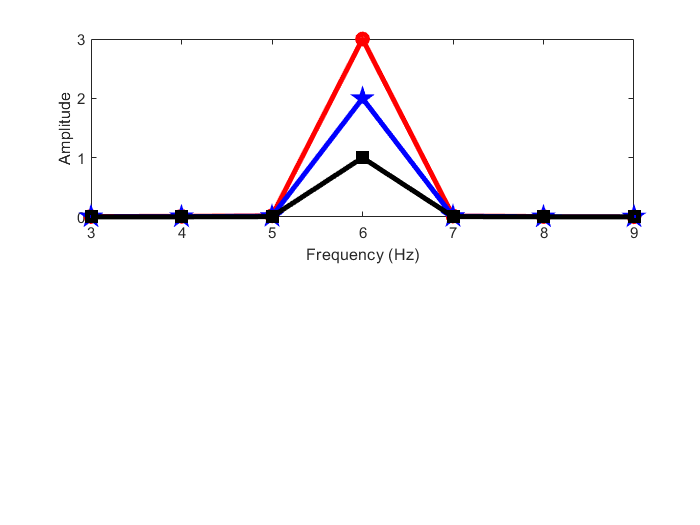

% extract amplitude using Pythagorian theorem
amp1 = sqrt( imag(fCoefs1).^2 + real(fCoefs1).^2 );
amp2 = sqrt( imag(fCoefs2).^2 + real(fCoefs2).^2 );
amp3 = sqrt( imag(fCoefs3).^2 + real(fCoefs3).^2 );

% extract amplitude using the Matlab function abs
% amp1 = abs( fCoefs1 );
% amp2 = abs( fCoefs2 );
% amp3 = abs( fCoefs3 );

figure(6), clf

% plot amplitude spectrum
subplot(211)
plot(hz,2*amp1(1:length(hz)),'ro-','linew',3), hold on
plot(hz,2*amp2(1:length(hz)),'bp-','linew',3)
plot(hz,2*amp3(1:length(hz)),'ks-','linew',3)
set(gca,'xlim',[freq-3 freq+3])
xlabel('Frequency (Hz)'), ylabel('Amplitude')

## and now for phase...

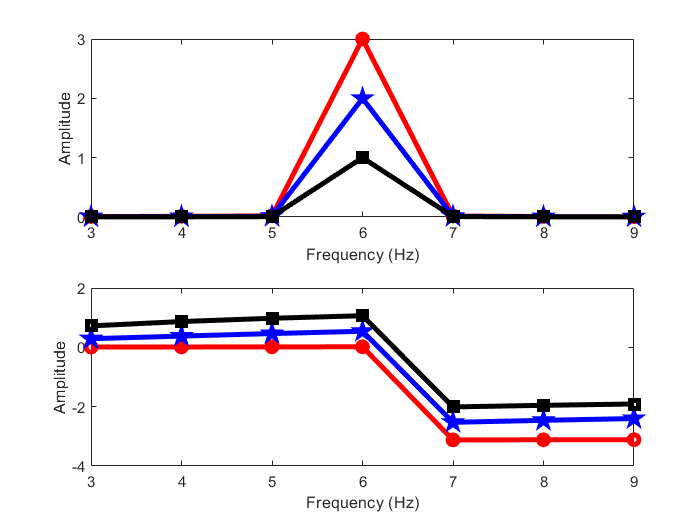

% extract phase angles using trigonometry
phs1 = atan2( imag(fCoefs1) , real(fCoefs1) );
phs2 = atan2( imag(fCoefs2) , real(fCoefs2) );
phs3 = atan2( imag(fCoefs3) , real(fCoefs3) );

% extract phase angles using Matlab function angle
% phs1 = angle( fCoefs1 );
% phs2 = angle( fCoefs2 );
% phs3 = angle( fCoefs3 );


% plot phase spectrum
subplot(212)
plot(hz,phs1(1:length(hz)),'ro-','linew',3), hold on
plot(hz,phs2(1:length(hz)),'bp-','linew',3)
plot(hz,phs3(1:length(hz)),'ks-','linew',3)
set(gca,'xlim',[freq-3 freq+3])
xlabel('Frequency (Hz)'), ylabel('Amplitude')

## end.